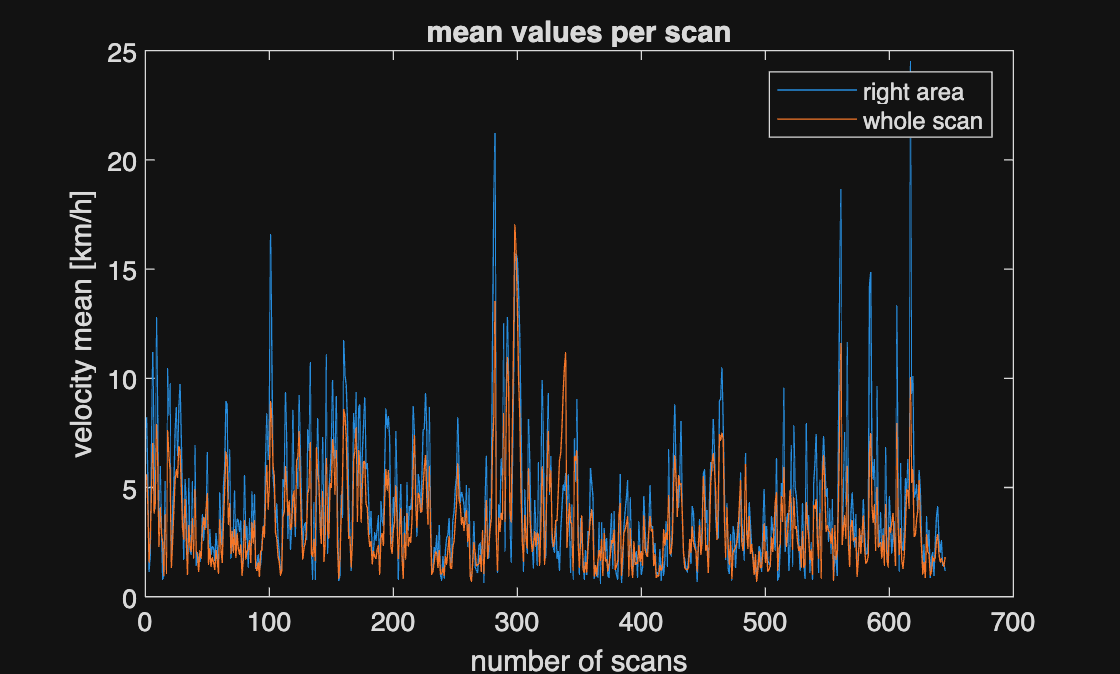

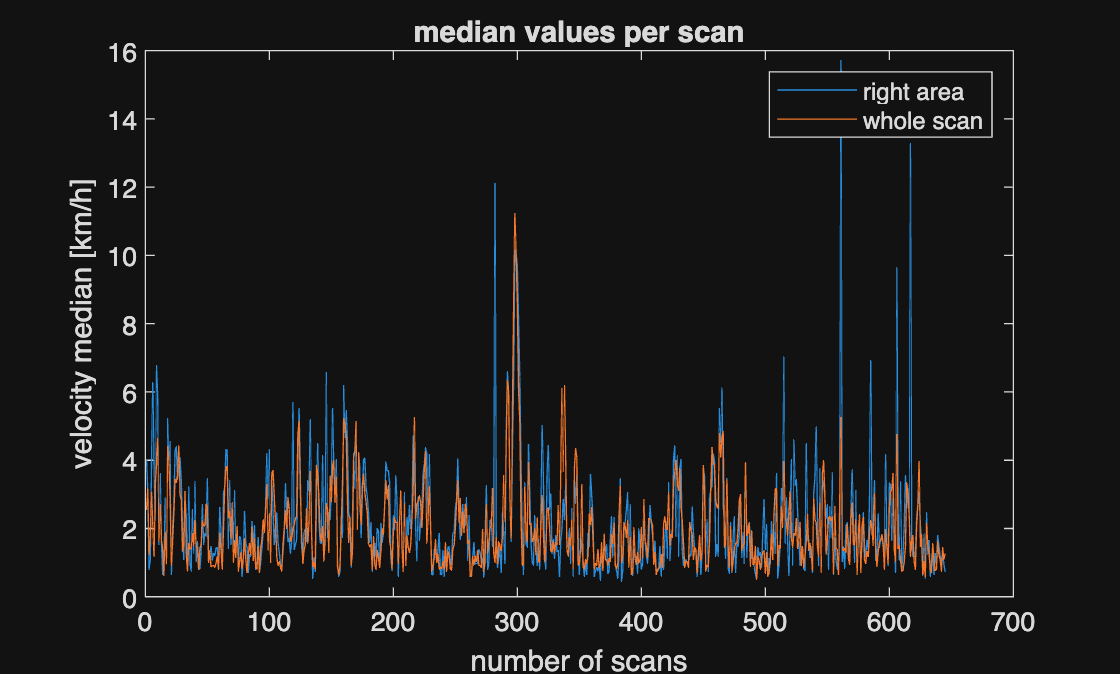

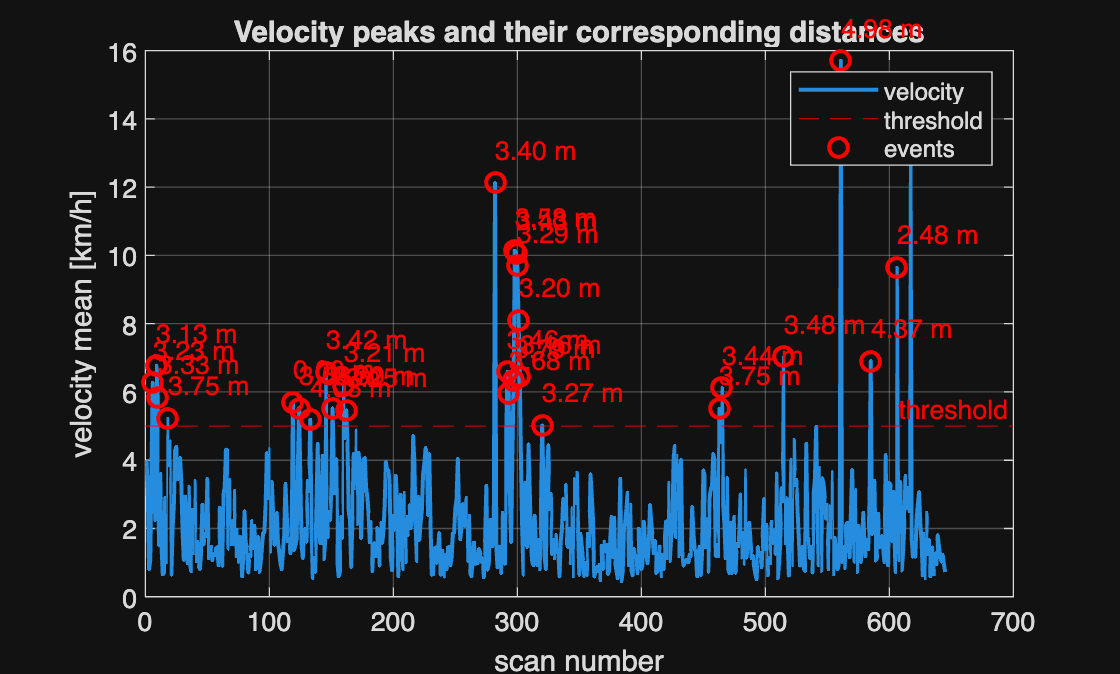

clc; clear; close all;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% change suffix from 1 to 5 to get different data files
%
filepath_r_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_test_street_2.csv';
filepath_xy_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_xy_test_street_2.csv';
filepath_vx_vy = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_velocities_x_y_test_street_2.csv';
filepath_rssi = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_rssi_test_street_2.csv';

% ===== to cut file uncomment the function below ===== %

%trimLidarData(filepath_xy_scan , filepath_r_scan, filepath_vx_vy, filepath_rssi, 1000, 1600)

% ===== load data ===== %

xy_data = readmatrix(filepath_xy_scan);
r_data = readmatrix(filepath_r_scan);
v_data = readmatrix(filepath_vx_vy);
rssi_data = readmatrix(filepath_rssi);

t_r_ = r_data(:,1);
r_all_ = r_data(:,3);

t_xy_ = xy_data(:,1); % each scan has the same time value! each point from a single scan <-> time 
x_all_ = xy_data(:, 2);
y_all_ = xy_data(:, 3);

t_velocity = v_data(:,1);
vx_all= v_data(:,2); 
vy_all = v_data(:,3);  
v = v_data(:,4);

t_rssi = rssi_data(:,1); 
rssi = rssi_data(:,2);

% ===== synchronize ===== %

scanPointNumbers = 421;  % 421 current number of points (811 for earlier measurements)

numScans_xy = floor(length(x_all_) / scanPointNumbers);
numScans_v  = floor(length(vx_all) / scanPointNumbers);
numScans_rssi = floor(length(rssi) / scanPointNumbers);

% ===== keep only the values with proper velocity ===== % filtered values
% are mostly matricies, each row represents a single scan. 421 points (col)
% for each scan 

[x_filtered, y_filtered, vx_filtered, vy_filtered, v_filtered, rssi_filterd, r_filtered]= filterAllValuesWithProperVelocities(x_all_, y_all_, vx_all, vy_all, v, rssi, r_all_, scanPointNumbers);

% ===== calculate mean/median values for each scan ===== % (column 1: right side, colum 2: left side, column 3: whole scan)

[v_mean, v_median, point_index_median_velocities] = computeMeanMedianVelocity(v_filtered, r_filtered, scanPointNumbers);

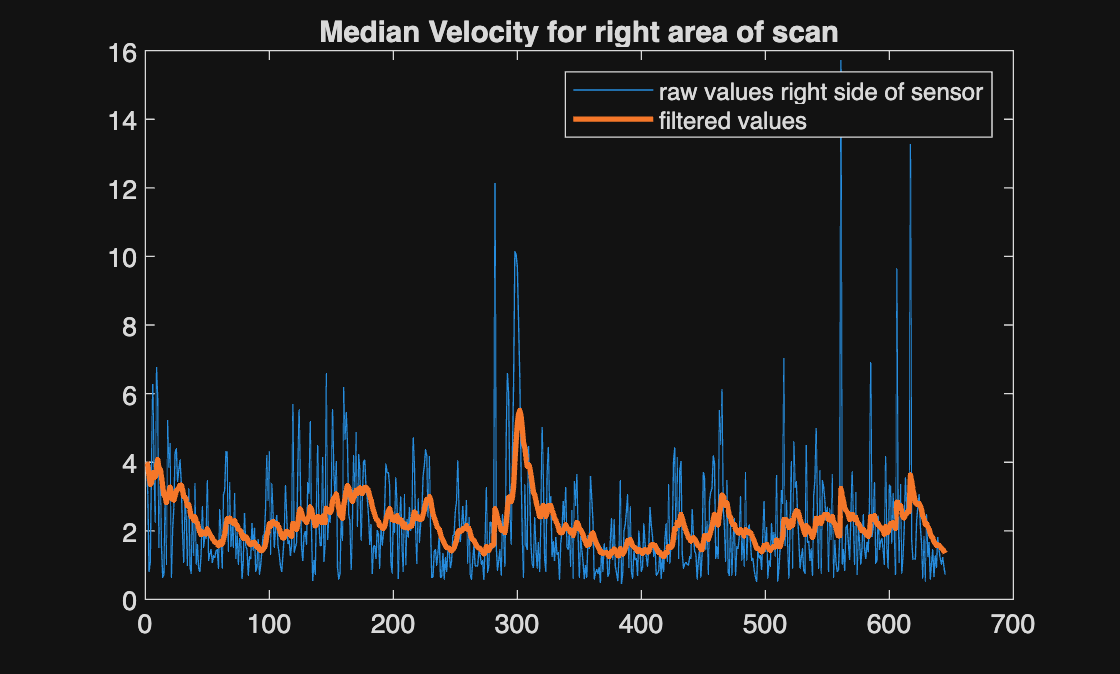

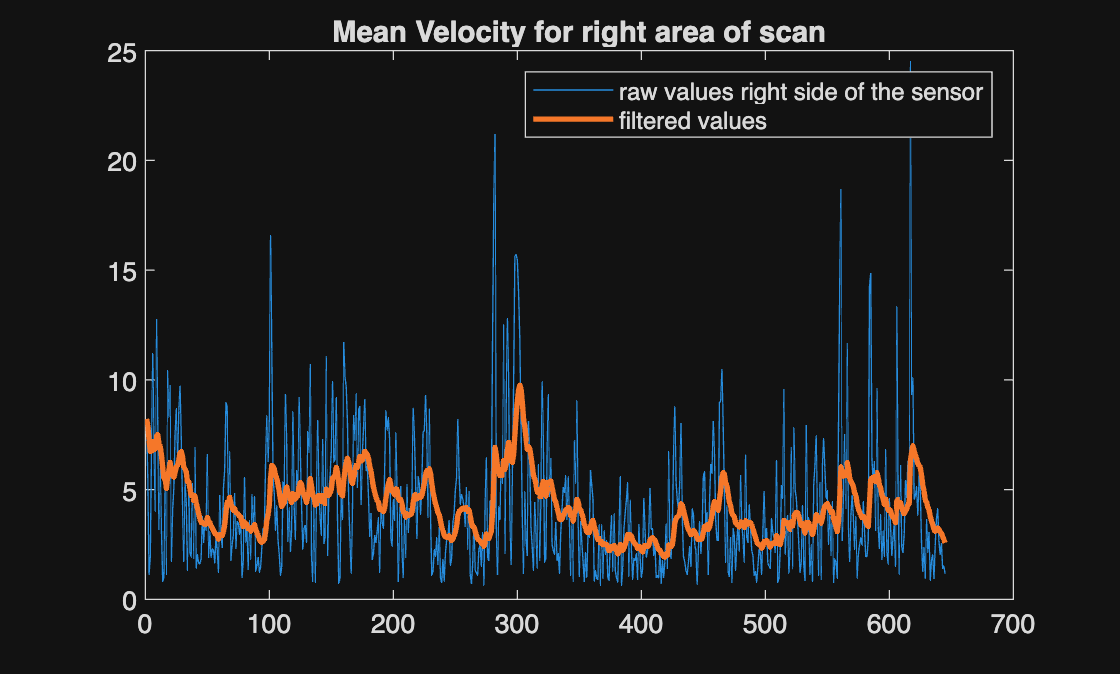


% ===== filtering the median and mean values for ego motion estimation ===== %

[alphafiltered_median, alphafiltered_mean] = alphaFilter(v_median(:,1), v_mean(:,1)); % alpha filter to compute ego velocity


% ===== detect dangerous object ===== %

v_median_right_area = v_median(:,1);
overtakingCar = detectDangerousObject(v_median_right_area, point_index_median_velocities, rssi_filterd, r_filtered, alphafiltered_median);

scanNumber = 645

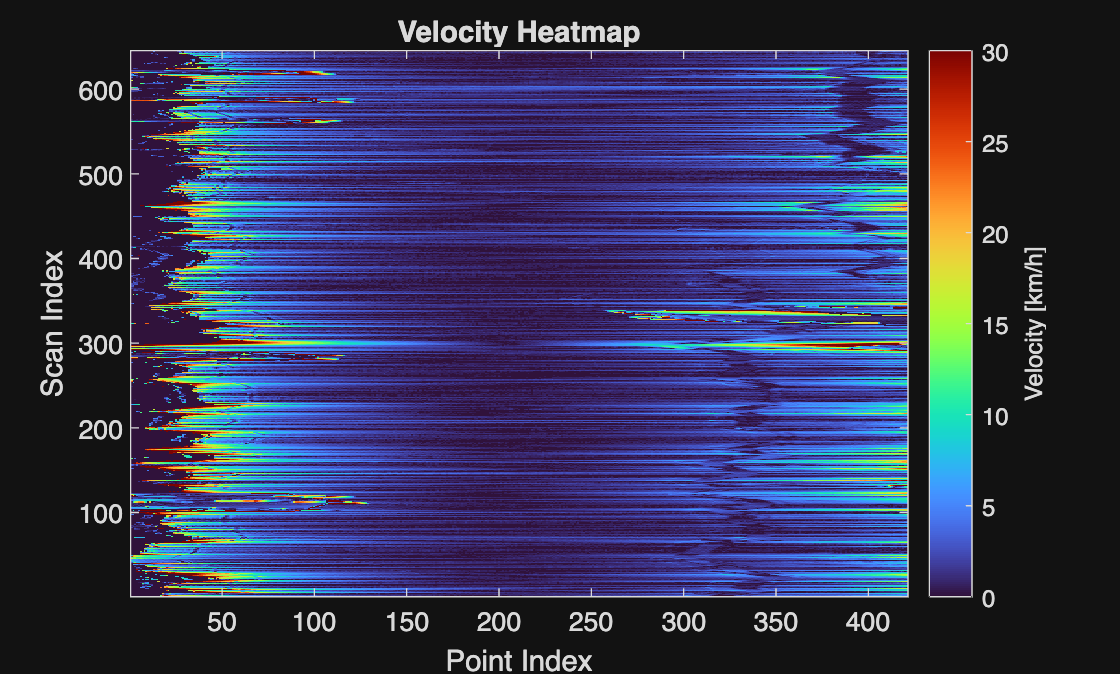

[x_points_in_critical_area, y_points_in_critical_area] = ExtractPointsInDangerousArea(x_filtered, y_filtered); 

% plotDanger(x_filtered, y_filtered, overtakingCar);
%plotPointsInCriticalArea(x_filtered, y_filtered, x_points_in_critical_area, y_points_in_critical_area); 

% ===== theta ===== %

%plotTheta(x_all_, y_all_, vx_all, vy_all);
%plotTheta(x_filtered, y_filtered, vx_filtered, vy_filtered);

% ===== plot direction of points as arrows ===== %

% plotDirectionalField(x_all_, y_all_, vx_all, vy_all); 
% plotDirectionalField(x_filtered, y_filtered, vx_filtered, vy_filtered);

%% ===== Velocity Heatmap =====
 
% heatmap(v_filtered);

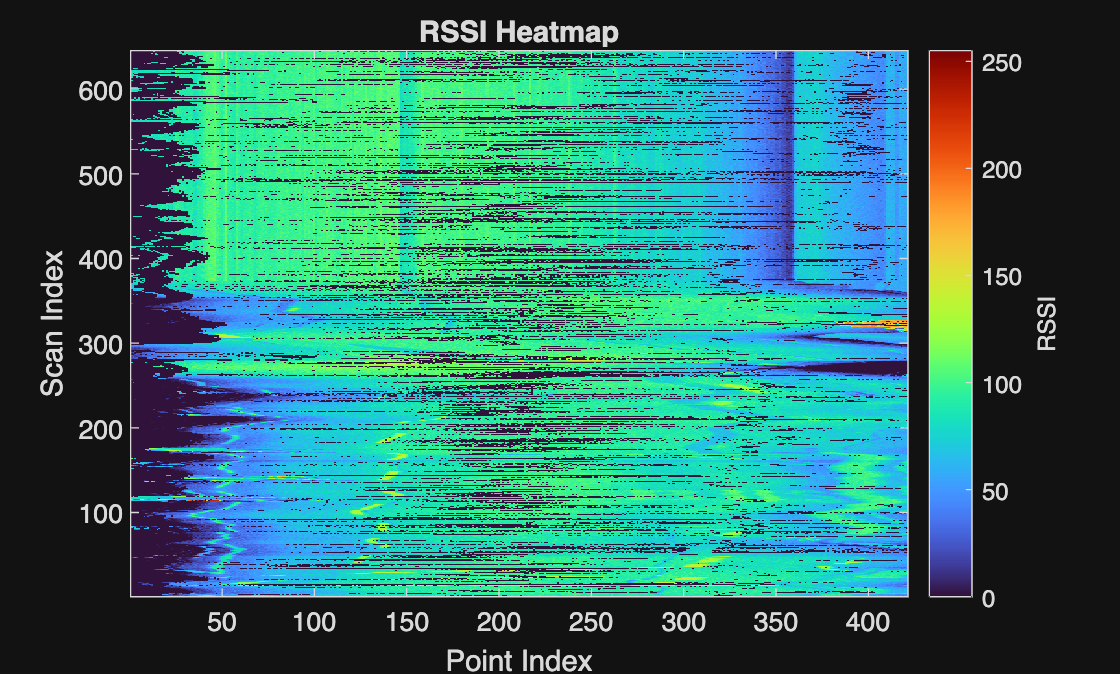

% plotHeatmap(rssi_filterd);


%% =====  Number of points with velocity ===== %%

% plotMovingPoints(v_filtered);


